%Sarwajeet Pratap Singh
%PRN: 20220802013
fprintf('Sarwajeet Pratap Singh')

Sarwajeet Pratap Singh

fprintf('PRN: 20220802013')

PRN: 20220802013

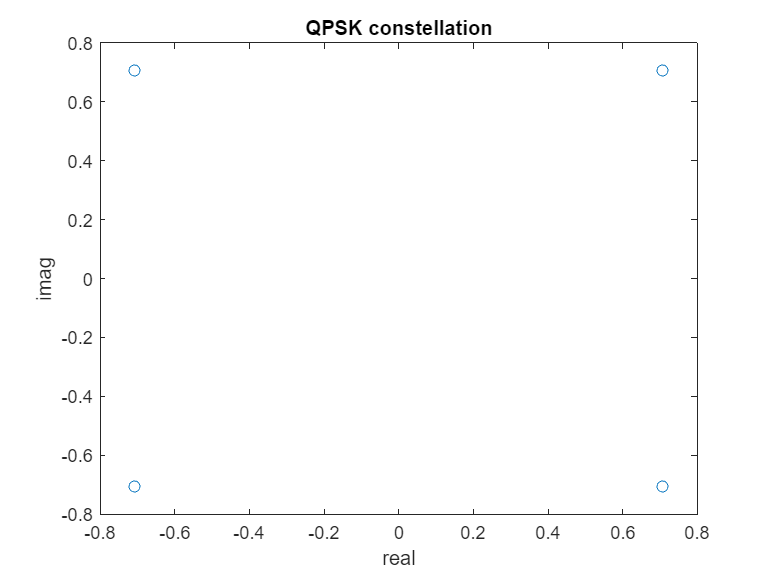

clear;
b = [1,0,0,0,1,1,0,1];  % Assign binary data bits
d = zeros(1, length(b)/2);  % Initialize d

for n = 1:length(b)/2
    p = b(2*n);
    q = b(2*n-1);
    if (q == 0) && (p == 0)
        d(n) = exp(1i * pi/4);  % 45 degrees
    end
    if (q == 1) && (p == 0)
        d(n) = exp(1i * 3 * pi/4);  % 135 degrees
    end
    if (q == 1) && (p == 1)
        d(n) = exp(1i * 5 * pi/4);  % 225 degrees
    end
    if (q == 0) && (p == 1)
        d(n) = exp(1i * 7 * pi/4);  % 315 degrees
    end
end
qpsk = d;
plot(d, 'o');
xlabel('real');
ylabel('imag');
title('QPSK constellation');